# Sample Generator

BE CAREFUL, THIS SCRIPT CAN OVERWRITE FILES

Expert data generation for behavioural cloning

clc
clear all
close all
generate_data = true;         % Run data generation simulation
buffer_name   = 'train10k'; % train/validation
Nepisodes     = 10000;         % Number of simulations

% Randomness control
if contains(buffer_name, 'train')
    0
    rng(0)
elseif strcmp(buffer_name, 'validation')
    1
    rng(1)
end

ans = 0

## Parameters

Simulation and control steps

Ts = 100e-6;    % Sampling time
Ti = 10e-6;	    % Integration step

Ax0 = 7000;
Ay0 = 5000;
fx0 = 50;
fy0 = 50;
wx0 = 2*pi*fx0;
wy0 = 2*pi*fy0;

[ix_max, iy_max, is_max, vo_max, vB_max, VCdiff] = max_values(Ax0, Ay0)

ix_max = 142.8571

iy_max = 200

is_max = 228.5714

vo_max = 6000

vB_max = 12000

VCdiff = 0.0020

## External system (IOGrid)

Specifications

specsIOGrid = struct();

specsIOGrid.Ti = Ti;
specsIOGrid.Ax = Ax0;
specsIOGrid.fx = fx0;
specsIOGrid.Ay = Ay0;
specsIOGrid.fy = fy0;

Initial values

init_valsIOGrid = struct();

init_valsIOGrid.gx0 = 0;
init_valsIOGrid.gy0 = 0;

Create object

IOGrid = ClassIOGrid(specsIOGrid, init_valsIOGrid)

IOGrid =   ClassIOGrid with properties:

     Ti: 1.0000e-05
     Ax: 7000
     Ay: 5000
     fx: 50
     fy: 50
     wx: 314.1593
     wy: 314.1593
     gx: 0
     gy: 0
    vxy: [6×1 double]

## Modular Multilevel Matrix Converter (M3C)

Specifications

specsM3C = struct();

specsM3C.Ti  = Ti;       % Integration step
specsM3C.R   = 1e-3;     % Branch resistance
specsM3C.L   = 20e-3;    % Branch inductance
specsM3C.Csm = 20e-3;    % Submodule capacitance
specsM3C.Nsm = 4;        % Submodules per cluster
specsM3C.Rx  = 0.1e-3;   % Input filter resistance
specsM3C.Lx  = 1e-3;     % Input filter inductance
specsM3C.Ry  = 0.1e-3;   % Output filter resistance
specsM3C.Ly  = 1e-3;     % Output filter inductance

Initial values

init_valsM3C = struct();

init_valsM3C.is0 = zeros(9, 1);                     % Cluster current
init_valsM3C.vc0 = (vB_max + vo_max) * ones(9, 1);  % Cluster capacitor voltage

Create object

M3C = ClassM3C(specsM3C, init_valsM3C)

M3C =   ClassM3C with properties:

        A: [6×9 double]
    pinvA: [9×6 double]
        m: 9
        N: [9×4 double]
        n: 4
    pinvN: [4×9 double]
       Ti: 1.0000e-05
        R: 1.0000e-03
        L: 0.0200
      Csm: 0.0200
      Nsm: 4
        C: 0.0050
       Rx: 1.0000e-04
       Lx: 1.0000e-03
       Ry: 1.0000e-04
       Ly: 1.0000e-03
       As: [9×9 double]
       Bs: [9×9 double]
       Es: [9×9 double]
       Ad: [9×9 double]
       Bd: [9×9 double]
       Ed: [9×9 double]
      ixy: [6×1 double]
       is: [9×1 double]
      pis: [9×1 double]
       iB: [9×1 double]
       iz: [9×1 double]
       ie: [4×1 double]
       vc: [9×1 double]
       Ec: [9×1 double]

## Cluster Energy Model Predictive Controller (CEMPC)

Cluster energy and capacitor voltage references

vc_mean_ref = vB_max + vo_max;
Ec_mean_ref = M3C.C/2 * vc_mean_ref^2;

vc_ref = vc_mean_ref * ones(9, 1);
Ec_ref = Ec_mean_ref * ones(9, 1);

Specifications

specsCEMPC = struct();

specsCEMPC.Ts       = Ts;
specsCEMPC.m        = M3C.m;
specsCEMPC.n        = M3C.n;
specsCEMPC.N        = M3C.N;
specsCEMPC.is_max   = is_max;
specsCEMPC.vo_max   = vo_max;
specsCEMPC.lambda_z = (Ec_mean_ref/is_max)^2 * 0.5e-6;
specsCEMPC.lambda_o = (Ec_mean_ref/vo_max)^2 * 0.5e-6;
specsCEMPC.lmax     = 10;
specsCEMPC.Np       = 1;

specsCEMPC.lambda_z

ans = 6.2791

specsCEMPC.lambda_o

ans = 0.0091

Create object

CEMPC = ClassCEMPC(specsCEMPC)

CEMPC =   ClassCEMPC with properties:

            Ts: 1.0000e-04
             m: 9
             n: 4
            NN: [9×4 double]
           one: [9×1 double]
            Np: 1
        is_max: 228.5714
        vo_max: 6000
      lambda_z: 6.2791
      lambda_o: 0.0091
          lmax: 10
     options_i: [1×1 mpcActiveSetOptions]
     options_v: [1×1 mpcActiveSetOptions]
        ie_ref: [4×1 double]
        iz_ref: [9×1 double]
        vo_ref: 0
           iAi: [18×1 logical]
           iAv: [2×1 logical]
    exitflag_i: -3
    exitflag_v: -3
      exitflag: -3
           Tex: 0

## Reference Frame Transform (RFT)

RFT = reference_frame_transforms();
RFT.abc2dq

ans = function_handle with value:
    @(g)(2/3)*[cos(g),cos(g-2*pi/3),cos(g+2*pi/3);-sin(g),-sin(g-2*pi/3),-sin(g+2*pi/3)]

RFT.abc2ab

ans =     0.6667   -0.3333   -0.3333
         0    0.5774   -0.5774


RFT.ab2abc

ans =     1.0000         0
   -0.5000    0.8660
   -0.5000   -0.8660


## Buffer

Initialize buffer

Ninputs = 1+9+6+6

Ninputs = 22

% mean(Ec), Ec-mean(Ec), vxy, ixy

Ninputs = 1+9+4+4+4

Ninputs = 22

% mean(Ec), Ec-mean(Ec)
% vxac, vxbc, vyac, vybc
% ixa, ixb, iya, iyb
% px1, px2, py1, py2

Noutputs = 5

Noutputs = 5

% ie, vo

Buffer has $N_{\textrm{episodes}} \cdot N_{\textrm{horizon}}$ observations and actions of dimensions $N_{\textrm{inputs}}$ and $N_{\textrm{outputs}}$, respectively

buffer = zeros(Nepisodes, Ninputs+Noutputs);
size(buffer)

ans =        10000          27


Number of active constraints per example

active_constraints_list = zeros(2, Nepisodes);

Exit flag to remove unfeasible examples

exitflag_list = zeros(1, Nepisodes);

## Generate input data

Assumptions:

- The selected horizon is considered to capture long enough trajectories without comprimising too much the sample efficiency

- Three phase symmetric input/output voltages of constant amplitude

In each episode, the following variables and constants must be initialized:

- (9) Cluster capacitor voltage $v_c$, centered around vc_ref with $\pm$1% deviations or similar

- (9) Cluster currents $i_s$, centered around 0 with $\pm$is_max

- (2) Phase of external voltages gx and gy, between [0, 2*pi]

**SIMPLIFICATIONS FOR THE THESIS PROPOSAL (PROOF OF CONCEPT):**

- **Only cluster energy balance if **$N_{\textrm{horizon}} =1$**, the rest of the control loop is ignored for faster data generation**

- **Fixed external voltages amplitudes and frequencies**

- **For generalization purposes, it is needed to train the agent with different external voltages amplitudes and frequencies**

Ax = 7000, Ay = 5000, wx = wy = 2*pi*50

Create initial input data with selected sampling method

rng(0)
Ninit_values = 9+2+4+4 % vc (9), gx, gy, ix1, ix2, iy1, iy2, ie (4)

Ninit_values = 19

                       % vc (9), gx, gy, ix, gix, iy, giy, ie (4)
init_vals = lhsdesign(Nepisodes, Ninit_values)';
size(init_vals)

ans =           19       10000



% Cluster voltages
VC0 = ((2*init_vals(1:9, :)-1)*VCdiff+1) * vc_mean_ref;

% Input/output voltage angles
GX0 = init_vals(10, :) * 2*pi;
GY0 = init_vals(11, :) * 2*pi;

% External currents
ix1 = (2 * init_vals(12, :) - 1) * ix_max;
lb = -ix_max - min(0, ix1);
ub = ix_max - max(0, ix1);
ix2 = lb + (ub - lb) .* init_vals(13, :);
ix3 = -(ix1 + ix2);

iy1 = (2 * init_vals(14, :) - 1) * iy_max;
lb = -iy_max - min(0, iy1);
ub = iy_max - max(0, iy1);
iy2 = lb + (ub - lb) .* init_vals(15, :);
iy3 = -(iy1 + iy2);

ix_lhs = [ix1; ix2; ix3];
iy_lhs = [iy1; iy2; iy3];

for episode = 1:Nepisodes
    ix_lhs(:, episode) = ix_lhs(randperm(3), episode);
    iy_lhs(:, episode) = iy_lhs(randperm(3), episode);
end

% ixab_lhs = ix_max * init_vals(12, :) .* [cos(2*pi*init_vals(13, :)); sin(2*pi*init_vals(13, :))];
% iyab_lhs = iy_max * init_vals(14, :) .* [cos(2*pi*init_vals(15, :)); sin(2*pi*init_vals(15, :))];
% ix_lhs = RFT.ab2abc * ixab_lhs;
% iy_lhs = RFT.ab2abc * iyab_lhs;

ixy_lhs = [ix_lhs; iy_lhs];
iB_lhs = M3C.pinvA * ixy_lhs;

% Circulating currents
iz_lhs = M3C.N * (2 * init_vals(16:19, :) - 1);
alpha_min = @(alpha) abs(max(abs(iB_lhs(:) + iz_lhs(:) * alpha)) - is_max);
alpha = fminbnd(alpha_min, 0, 100)

alpha = 38.6546

iz_lhs = iz_lhs * alpha;

% Cluster currents
is_lhs = iB_lhs + iz_lhs;

max(abs(is_lhs(:)))

ans = 228.5715

max(abs(iB_lhs(:)))

ans = 114.0174

max(abs(ix_lhs(:)))

ans = 142.8479

max(abs(iy_lhs(:)))

ans = 199.9987

max(abs(iz_lhs(:)))

ans = 134.8563

ie_lhs=M3C.pinvN*iz_lhs;
max(abs(ie_lhs(:)))

ans = 38.6545


IS0 = is_lhs;

## Generate output data

if generate_data

init_valsIOGrid = struct();
init_valsM3C = struct();

% Initialize progress bar
h = waitbar(0, 'Generating Data...');

tic
for episode = 1:Nepisodes

% Reset CEMPC solver
CEMPC = CEMPC.reset();

% M3C
init_valsM3C.vc0 = VC0(:, episode); % Cluster capacitor voltages
init_valsM3C.is0 = IS0(:, episode); % Cluster currents
M3C = M3C.reset(init_valsM3C);
Ec = M3C.Ec;
vc = M3C.vc;
iB = M3C.iB;
ixy = M3C.ixy;

% Input/output grid voltages
init_valsIOGrid.gx0 = GX0(episode);  % Input grid voltage angle
init_valsIOGrid.gy0 = GY0(episode);  % Output grid voltage angle
IOGrid = IOGrid.reset(init_valsIOGrid);
vxy = IOGrid.vxy;
vB = M3C.A' * vxy;

% % Predict external voltages/currents
% vB_pred = predict_basic_assuming_symmetrical(    vxy, CEMPC.Np, IOGrid, Ts, RFT, M3C.A);
% iB_pred = predict_basic_assuming_symmetrical(M3C.ixy, CEMPC.Np, IOGrid, Ts, RFT, M3C.A);

% Cluster energy MPC
% CEMPC = CEMPC.control(M3C.Ec, vB_pred, iB_pred);

CEMPC = CEMPC.control(M3C.Ec, vB, iB, vc);

% Add to buffer
buffer(episode, 1)     = mean(Ec);
buffer(episode, 2:10)  = Ec - mean(Ec);

% buffer(episode, 11:16) = vxy;
% buffer(episode, 17:22) = ixy;
% buffer(episode, 23:26) = CEMPC.ie_ref;
% buffer(episode, 27)    = CEMPC.vo_ref;
% exitflag_list(episode) = CEMPC.exitflag;

buffer(episode, 11:12) = vxy(1:2) - vxy(3);
buffer(episode, 13:14) = vxy(4:5) - vxy(6);
buffer(episode, 15:16) = ixy(1:2);
buffer(episode, 17:18) = ixy(4:5);
buffer(episode, 19:20) = (vxy(1:2) - vxy(3)) .* ixy(1:2);
buffer(episode, 21:22) = (vxy(4:5) - vxy(6)) .* ixy(4:5);

buffer(episode, 23:26) = CEMPC.ie_ref;
buffer(episode, 27)    = CEMPC.vo_ref;
exitflag_list(episode) = CEMPC.exitflag;
active_constraints_list(1, episode) = sum(CEMPC.iAi);
active_constraints_list(2, episode) = sum(CEMPC.iAv);

% Update progress bar
waitbar(episode/Nepisodes, h, sprintf('Generating Data: %d%%', round((episode/Nepisodes)*100)));

end
toc

% Close progress bar
close(h)

end

Elapsed time is 0.015736 seconds.


Filter non feasible examples

mask = exitflag_list == 1;
buffer = buffer(mask, :)

buffer = 1.0e+06 *

    0.8096    0.0019   -0.0026   -0.0015   -0.0008    0.0030   -0.0002    0.0015    0.0002   -0.0015    0.0004   -0.0103    0.0074    0.0076   -0.0001    0.0001   -0.0002    0.0001   -0.0495   -0.6054   -1.1587    1.1210    0.0003   -0.0000   -0.0001    0.0000   -0.0084
    0.8102    0.0023    0.0002   -0.0012   -0.0022    0.0028   -0.0025   -0.0021    0.0030   -0.0003    0.0084    0.0118   -0.0063   -0.0083   -0.0000    0.0000   -0.0000    0.0001   -0.1192    0.4625    0.1268   -1.0269   -0.0002    0.0000    0.0000   -0.0001    0.0095
    0.8103   -0.0029   -0.0012   -0.0022    0.0003    0.0027   -0.0011    0.0018    0.0009    0.0017    0.0117    0.0087   -0.0061    0.0022    0.0001   -0.0001    0.0001    0.0000    1.0759   -0.6220   -0.4942    0.0315   -0.0001    0.0001    0.0002   -0.0000    0.0083
    0.8092   -0.0023    0.0018   -0.0004    0.0036    0.0017   -0.0019   -0.0014    0.0008   -0.0017    0.0078    0.0119   -0.0067   -0.0081   -0.0001    0.0000    0.0

Count active constraints

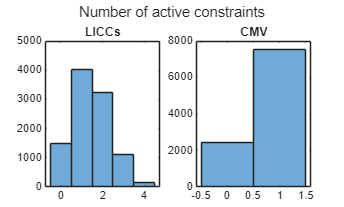

figure
subplot(1, 2, 1)
histogram(active_constraints_list(1, :))
title('LICCs')
subplot(1, 2, 2)
histogram(active_constraints_list(2, :))
title('CMV')
sgtitle('Number of active constraints')

Save generated data

buffer_struct = struct();
buffer_struct.X = buffer(:, 1:Ninputs)';
buffer_struct.Y = buffer(:, Ninputs+1:Ninputs+Noutputs)';
buffer = buffer_struct;
save(strcat('ImitationLearning\TrainingData\Data\', buffer_name, '.mat'), 'buffer')

Run training and testing

% run('FFNN.mlx')
% run('Simulate.mlx')